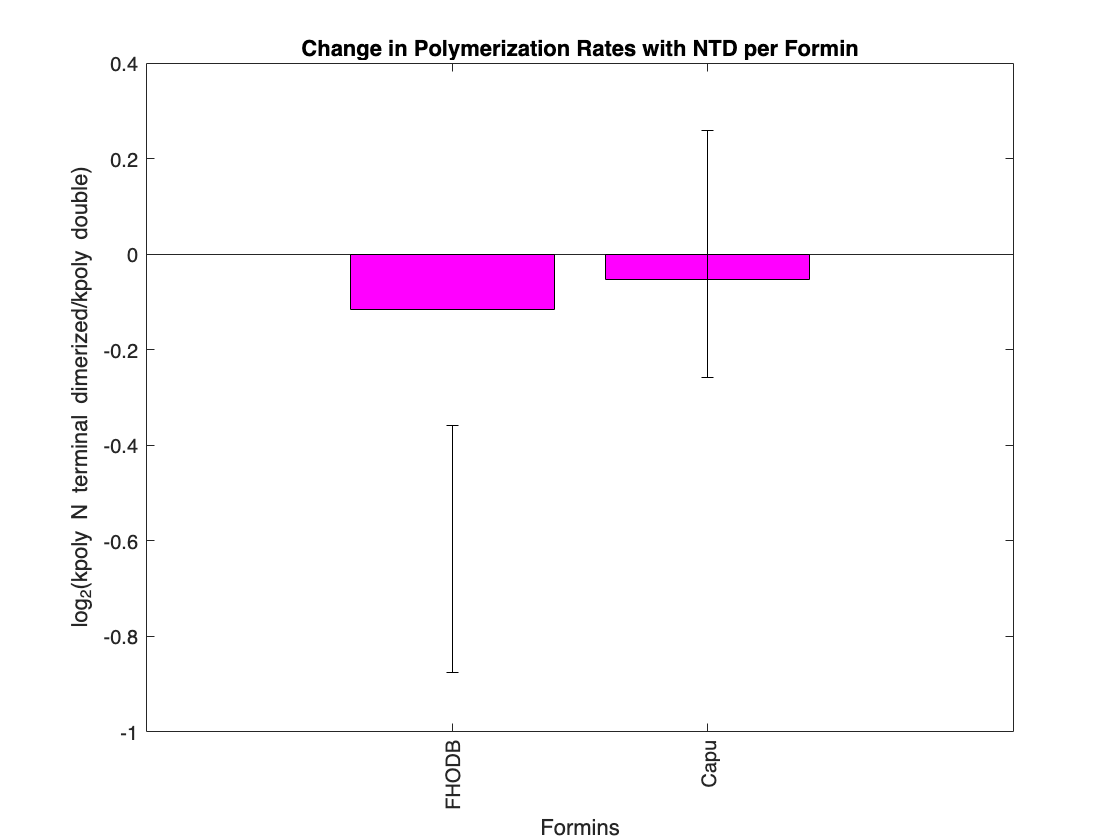

i=1;
%vals=T2{i,3:7};
%vals=T{i,2:6};
%vals=T3{i,8:12};
%vals=reasonable{i,8:12};
%vals=T_err{i,6:10};
%vals=T_err_topNTD{i,6:10};
%vals=T_noF3D37{i,6:10};
%vals=abs(params_FHOD);
%vals=FHOD_T{i,2:6};
%vals=T_SOS_FHOD2{i,6:10};
%vals=Capu_T{i,2:6};
%vals=Capu_T_reas{i,2:6};
%vals=abs(params);
%vals=z2;
%vals=T_calcr{i,6:10};
%vals=T_err_r_bs20{i,6:10};
%vals=T_err_r_bs35{i,6:10};
%vals=T_err_r_F3D37_bs35{i,6:10};
% vals=T{i,4:8};
% vals=abs(vals);
%vals=T_err_34{i,6:10};
%vals=T_err_34_rPFrev_scale{i,6:10};
vals=T_err_34_rPFrev_scale_kpaf_scale{i,6:10};
%vals=T_r_34_rPFrev_scale_kpaf_scale{i,6:10};
%vals=T_r_34_rPFrev_scale{i,6:10};
%vals=T_r_34{i,6:10};


vals=num2cell(vals);

% x=[...
%         (log2(FHOD.kdim(vals{:})./(FHOD.kdob(vals{:})))),...
%         (log2(Capu.kdim(vals{:})./(Capu.kdob(vals{:}))))...
%     ];

% x=[...
%         (log2(FHOD.kdimc(vals{:})./(FHOD.kdobc(vals{:})))),...
%         (log2(Capu.kdimc(vals{:})./(Capu.kdobc(vals{:}))))...
%     ];

% x=[...
%         (log2(FHODbs20.kdim(vals{:})./(FHODbs20.kdob(vals{:})))),...
%         (log2(Capubs20.kdim(vals{:})./(Capubs20.kdob(vals{:}))))...
%     ];

% x=[...
%         (log2(FHODbs35.kdim(vals{:})./(FHODbs35.kdob(vals{:})))),...
%         (log2(Capubs35.kdim(vals{:})./(Capubs35.kdob(vals{:}))))...
%     ];

% x=[...
%         (log2(FHOD.kdim__rPFrev_scale(vals{:})./(FHOD.kdob__rPFrev_scale(vals{:})))),...
%         (log2(Capu.kdim__rPFrev_scale(vals{:})./(Capu.kdob__rPFrev_scale(vals{:}))))...
%     ];

x=[...
        (log2(FHOD.kdim__rPFrev_scale_kpaf_scale(vals{:})./(FHOD.kdob__rPFrev_scale_kpaf_scale(vals{:})))),...
        (log2(Capu.kdim__rPFrev_scale_kpaf_scale(vals{:})./(Capu.kdob__rPFrev_scale_kpaf_scale(vals{:}))))...
    ];

y={FHOD.name; Capu.name};
kpoly_table_ratio = table(x', 'RowNames', y);
kpoly_bar_ratio = bar(kpoly_table_ratio{:,:});
hold on
set(gca,'xtick',1:2, 'xticklabel',kpoly_table_ratio.Properties.RowNames)
xtickangle(90)
set(kpoly_bar_ratio(1), 'FaceColor','m')
errlow=[-0.2584555583 -0.2584555583];
errhigh=[0.2584555583 0.2584555583];
er = errorbar([1 2],[-0.6172640408 0], errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';
xlabel('Formins')
ylabel('log_2(kpoly N terminal dimerized/kpoly double)')

%ylim([-0.62 0.3])
%ylim([-0.05 0.1])

hold off
title('Change in Polymerization Rates with NTD per Formin')

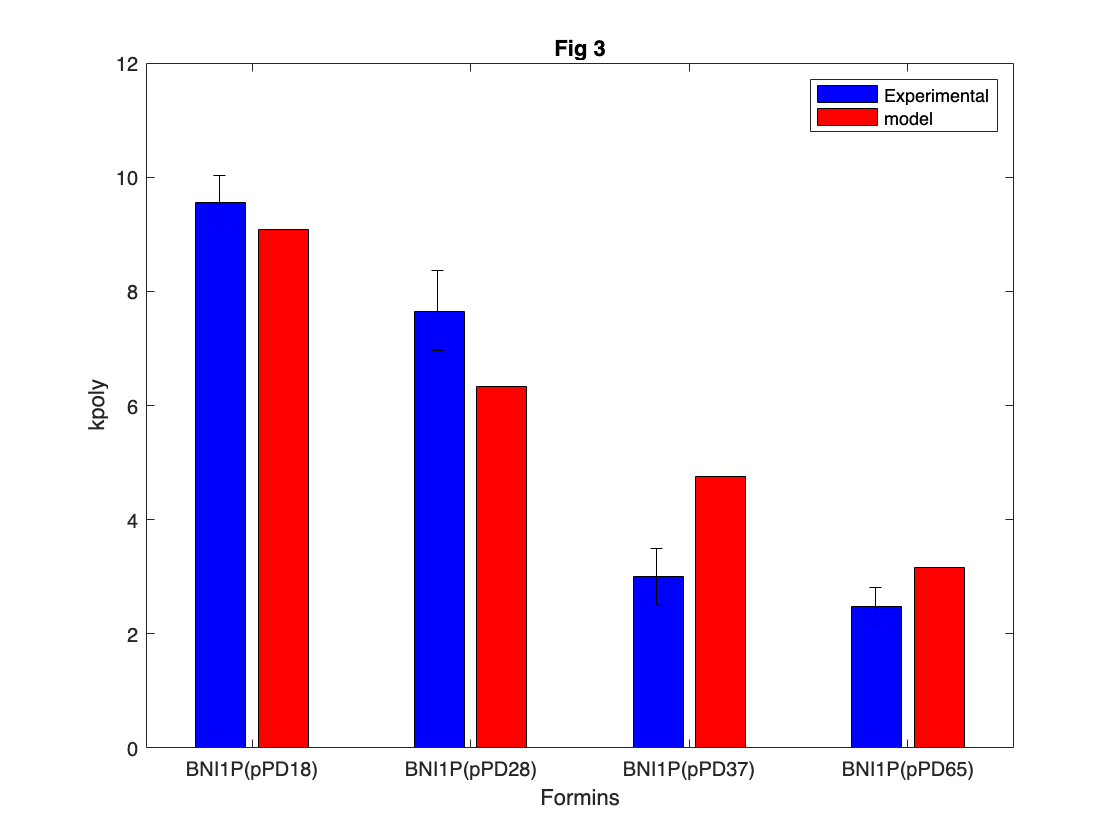

%kpolybar=bar([fig3k',fig3ksimf(vals{:})]);
%kpolybar=bar([fig3k',fig3ksimfc(vals{:})]);
%kpolybar=bar([fig3k',fig3ksimf_bs20(vals{:})]);
%kpolybar=bar([fig3k',fig3ksimf_rPFrev_scale(vals{:})]);
kpolybar=bar([fig3k',fig3ksimf_rPFrev_scale_kpaf_scale(vals{:})]);



set(gca,'xticklabel',{fig3sim.name});
hold on

er = errorbar([0.85 1.85 2.85 3.85],fig3k', fig3_err_bot,fig3_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

    set(kpolybar(1), 'FaceColor','b');
    set(kpolybar(2), 'FaceColor','r');
    legend( 'Experimental', 'model');
    xlabel('Formins');
    ylabel('kpoly');
    title("Fig 3")
    hold off

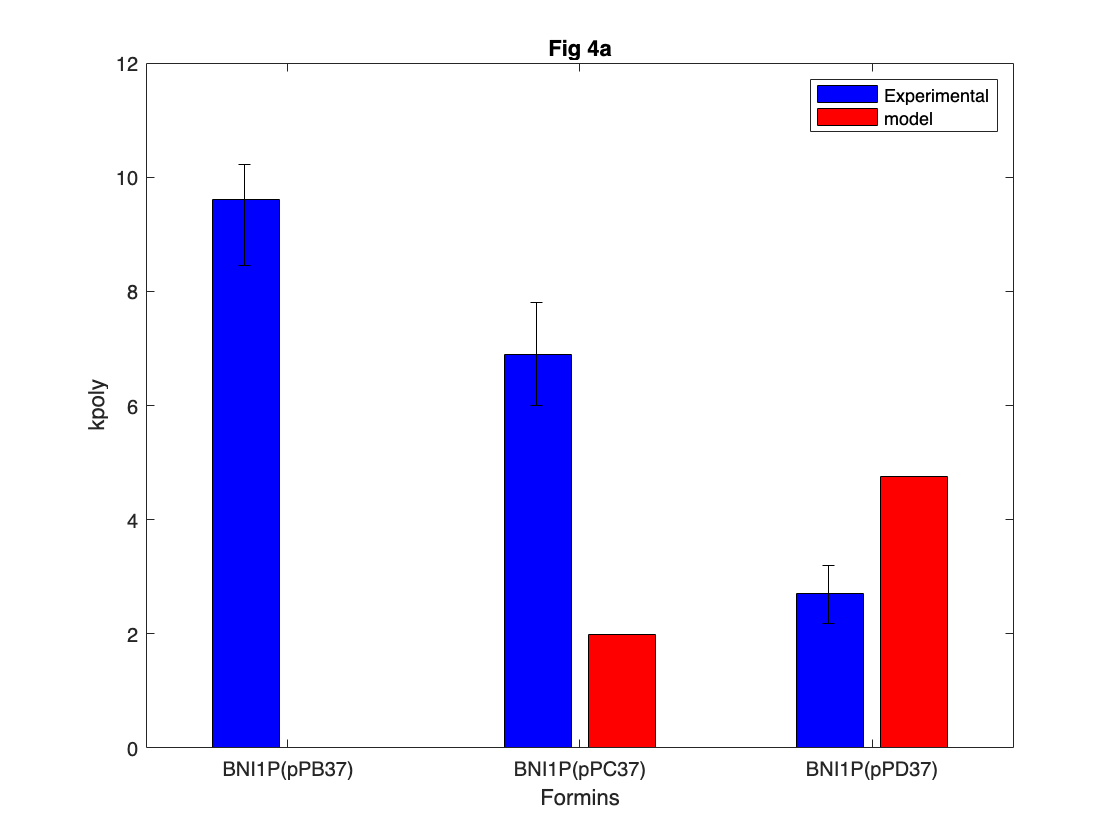

%kpolybar=bar([fig4ak',fig4aksimf(vals{:})]);
%kpolybar=bar([fig4ak',fig4aksimfc(vals{:})]);
%kpolybar=bar([fig4ak',fig4aksimf_bs20(vals{:})]);
%kpolybar=bar([fig4ak',fig4aksimf_rPFrev_scale(vals{:})]);
kpolybar=bar([fig4ak',fig4aksimf_rPFrev_scale_kpaf_scale(vals{:})]);



set(gca,'xticklabel',{fig4asim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ak', fig4_err_bot,fig4_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4a")
hold off

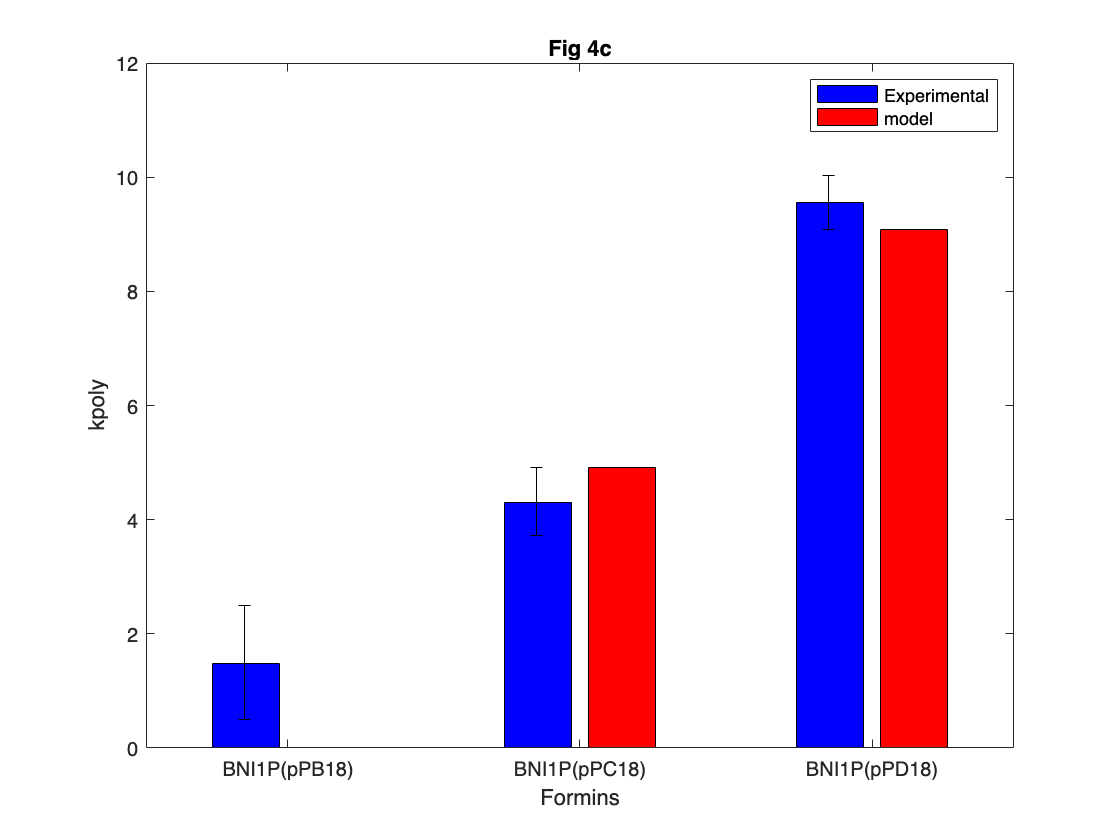

%kpolybar=bar([fig4ck',fig4cksimf(vals{:})]);
%kpolybar=bar([fig4ck',fig4cksimfc(vals{:})]);
%kpolybar=bar([fig4ck',fig4cksimf_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);
%kpolybar=bar([fig4ck',fig4cksimf_rPFrev_scale(vals{:})]);
kpolybar=bar([fig4ck',fig4cksimf_rPFrev_scale_kpaf_scale(vals{:})]);

set(gca,'xticklabel',{fig4csim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ck', fig4c_err_bot,fig4c_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4c")
hold off

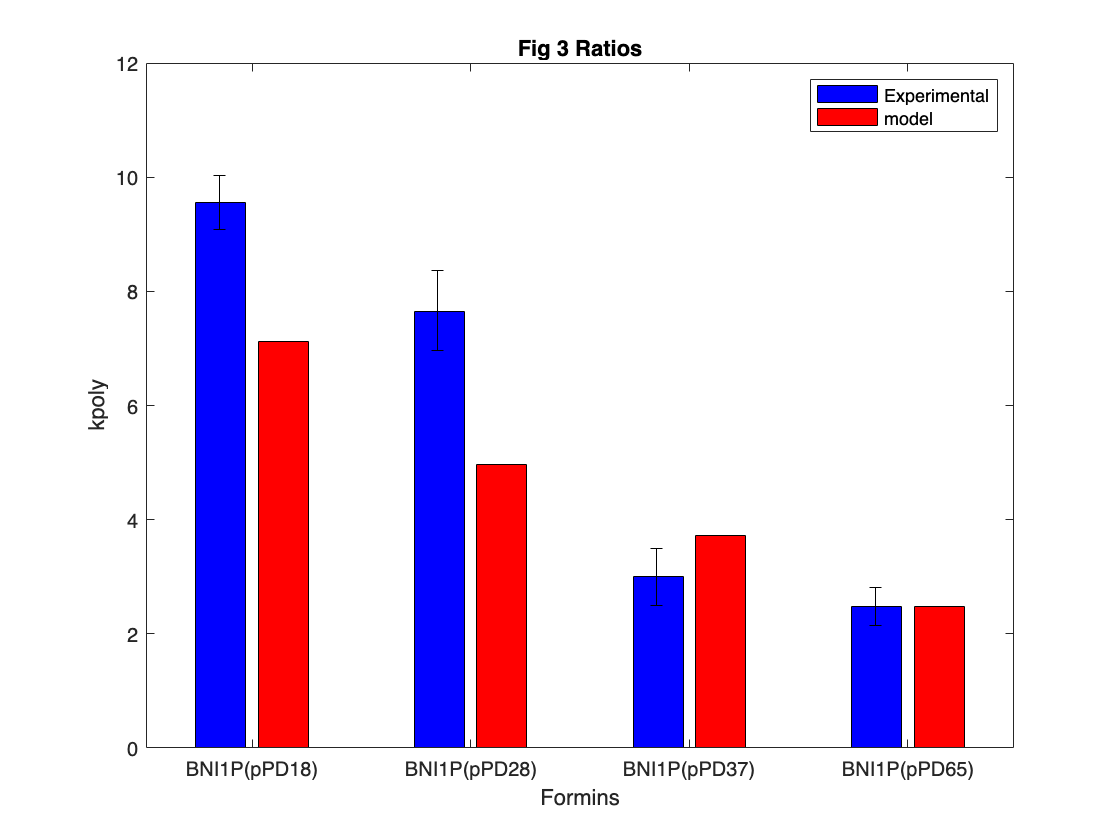


%kpolybar=bar([fig3k',fig3ksimf_r_bs20(vals{:})]);
%kpolybar=bar([fig3k',fig3ksimf_r(vals{:})]);
%kpolybar=bar([fig3k',fig3ksimf_r_rPFrev_scale(vals{:})]);
kpolybar=bar([fig3k',fig3ksimf_r_rPFrev_scale_kpaf_scale(vals{:})]);


set(gca,'xticklabel',{fig3sim.name});
hold on

er = errorbar([0.85 1.85 2.85 3.85],fig3k', fig3_err_bot,fig3_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

    set(kpolybar(1), 'FaceColor','b');
    set(kpolybar(2), 'FaceColor','r');
    legend( 'Experimental', 'model');
    xlabel('Formins');
    ylabel('kpoly');
    title("Fig 3 Ratios")
    hold off

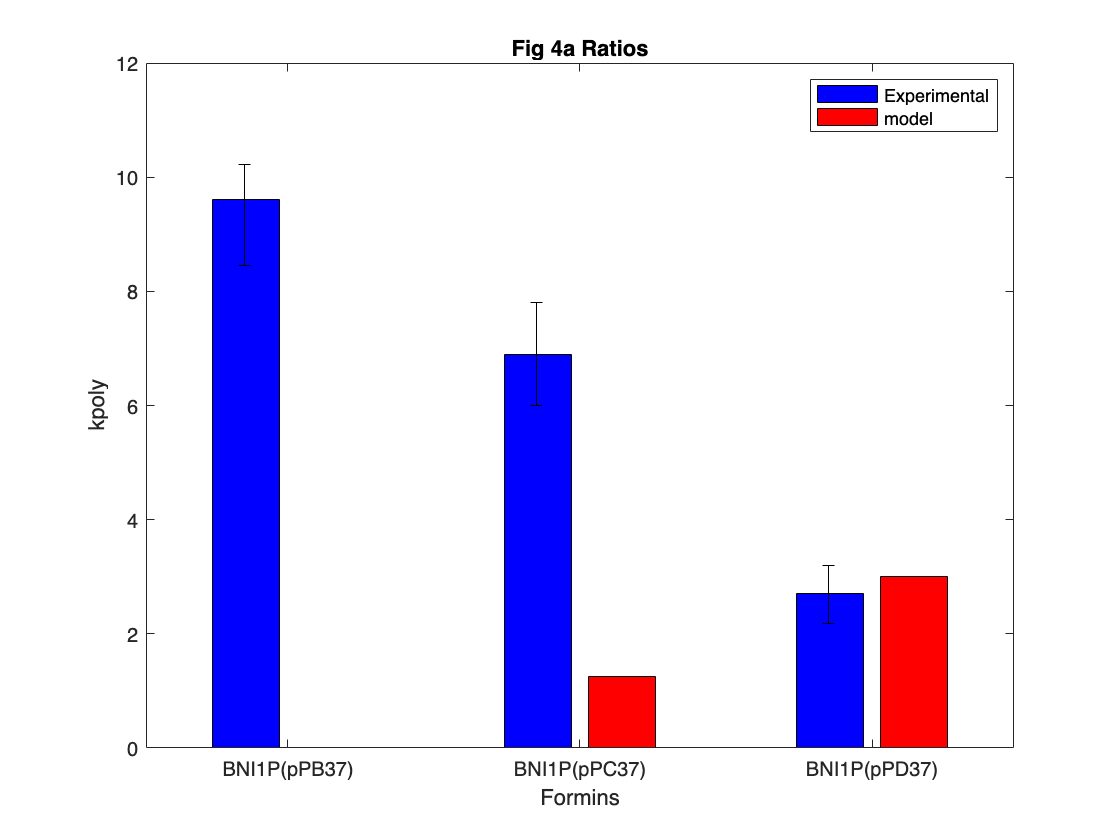

    
%kpolybar=bar([fig4ak',fig4aksimf_r_bs20(vals{:})]);
%kpolybar=bar([fig4ak',fig4aksimf_r(vals{:})]);
%kpolybar=bar([fig4ak',fig4aksimf_r_rPFrev_scale(vals{:})]);
kpolybar=bar([fig4ak',fig4aksimf_r_rPFrev_scale_kpaf_scale(vals{:})]);


set(gca,'xticklabel',{fig4asim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ak', fig4_err_bot,fig4_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4a Ratios")
hold off

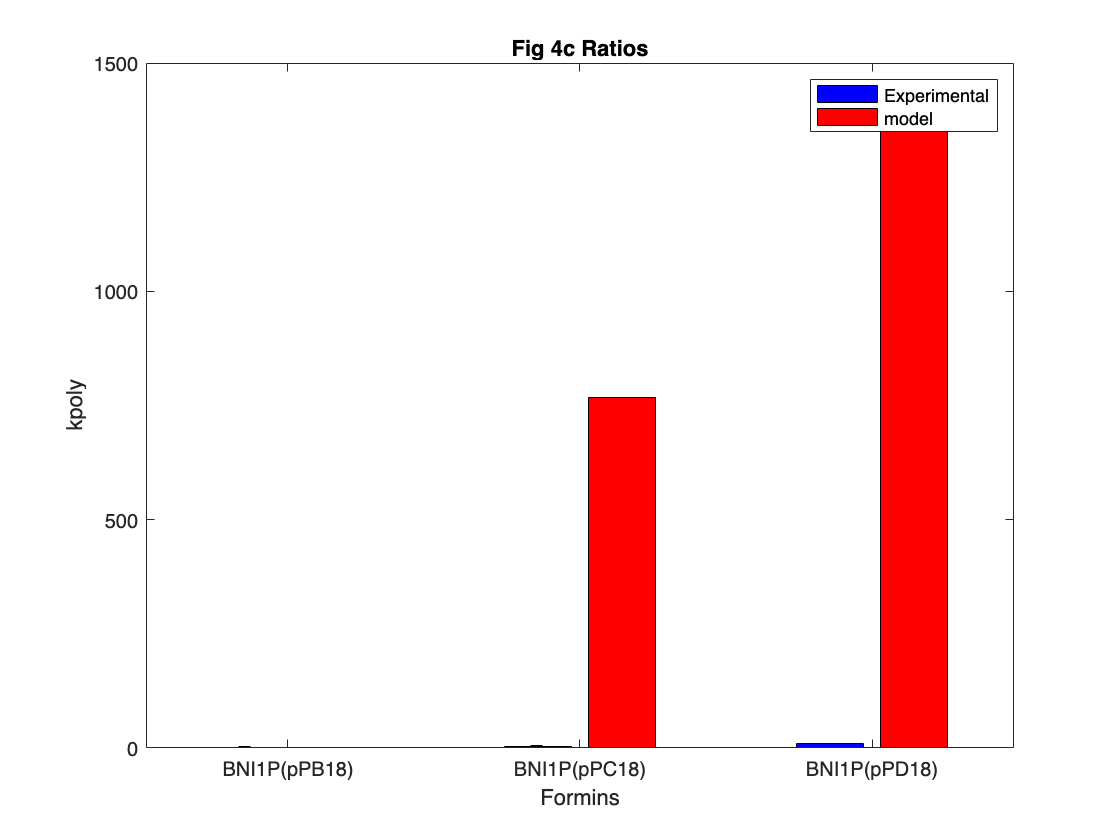

%kpolybar=bar([fig4ck',fig4cksimf_r_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);
%kpolybar=bar([fig4ck',fig4cksimf_r(vals{:})]);
%kpolybar=bar([fig4ck',fig4cksimf_r_rPFrev_scale(vals{:})]);
kpolybar=bar([fig4ck',fig4cksimf_r_rPFrev_scale_kpaf_scale(vals{:})]);

set(gca,'xticklabel',{fig4csim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ck', fig4c_err_bot,fig4c_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4c Ratios")
hold off